# **RS-WISP-04-02 Glideslope Transfer**

**WorkerInSpace**

**Hongseok Kim**

**2/6/2025**

## **I. Scope**

  When a chaser vehicle is required to apprach a target vehicle, an inbound glideslope guidance is invoked. In this scinario, thruster activity near the target is to be minimized to avoid plume impingement on the target vehicle and contamination of its surfaces. In addition, as a chaser approches the target, its relative velocity must diminish to certain safe limits. These requirements are fulfilled by designing a guidance trajectory wherein the range rate is proportional to the range. Such guidance trajectories are formulated in this document.

- **Note: in a glideslope with continuous thrusting, this relationship, although linear for the most part, is nonlinear near the end. In this document, a linear relationship between the range and range rate is postulated to be the mission design goal, whether the motion is in-plane or out-of-plane.**

### II. Background Knowledge for Inbound Decelerating Glideslope

  Following  vectors are demonstrated with respect to LVLH frame of target satellite

- At $t=0$, the chaser satellite is located at ${\mathit{\mathbf{r}}}_0$, with its relative velocity equal to ${\dot{\mathit{\mathbf{r}}} }_0^-$.

- The chaser vehicle is required to arrive at $\mathit{\mathbf{r}}={\mathit{\mathbf{r}}}_T$ in a transfer time $T$ with a velocity specified hereafter.

- A straight line from ${\mathit{\mathbf{r}}}_0$ to ${\mathit{\mathbf{r}}}_T$, denoted the vector $\vec{\rho}$, is the most natural commanded path for this transfer.

  Let ${\mathit{\mathbf{r}}}_c \left(t\right)$, measured from the target center of mass, be the commanded location of the chaser on this path at time $t$, $0\le t\le T$.

- Then the voundary values of ${\mathit{\mathbf{r}}}_c$ are ${\mathit{\mathbf{r}}}_c \left(0\right)={\mathit{\mathbf{r}}}_0$, ${\mathit{\mathbf{r}}}_c \left(T\right)={\mathit{\mathbf{r}}}_T$.

- The vector $\vec{\rho} \left(t\right)$ emanates from the tip of the vector ${\mathit{\mathbf{r}}}_T$ and it defines the commanded location of the chaser on the straight path from ${\mathit{\mathbf{r}}}_0$ to ${\mathit{\mathbf{r}}}_T$.

- The boundary conditions of $\vec{\rho} \left(t\right)$ are $\vec{\rho} \left(0\right)={\mathit{\mathbf{r}}}_0 -{\mathit{\mathbf{r}}}_T \equiv {\vec{\rho} }_0$, ${\vec{\rho} }_T =0$, and, at any time $t$, $\vec{\rho} \left(t\right)={\mathit{\mathbf{r}}}_c \left(t\right)={\mathit{\mathbf{r}}}_T$

  Because ${\mathit{\mathbf{r}}}_0 \equiv {\left\lbrack \begin{array}{ccc}
x_0  & y_0  & z_0 
\end{array}\right\rbrack }^T$ and ${\mathit{\mathbf{r}}}_T ={\left\lbrack \begin{array}{ccc}
x_T  & y_T  & z_T 
\end{array}\right\rbrack }^T$, the direction cosine of the vector $\vec{\rho}$ is given by:


$$\cos \;\alpha =\left(x_0 -x_T \right)/\rho_0 ,\;\;\;\;\cos \;\beta =\left(y_0 -y_T \right)/\rho_0 ,\;\;\;\cos \;\gamma =\left(z_0 -z_T \right)/\rho_0$$


  The direction of the strait path is then given by the unit vector ${\mathit{\mathbf{u}}}_p ={\left\lbrack \begin{array}{ccc}
\cos \;\alpha  & \cos \;\beta  & \cos \;\gamma 
\end{array}\right\rbrack }^T$, and the scalar distance $\rho$, the distance to go, along the vector $\vec{\rho}$, is $\vec{\rho} =\rho {\mathit{\mathbf{u}}}_{\rho }$.

- The glideslope guidance specifies the distance to go, $\rho$, as a function of time $\rho \left(t\right)$, so that the chaser is commanded to reach ${\mathit{\mathbf{r}}}_T$ from ${\mathit{\mathbf{r}}}_0$ in a period $T$ with the arrival commanded velocity ${\dot{\rho} }_T {\mathit{\mathbf{u}}}_{\rho }$ where ${\dot{\rho} }_T$, less than zero, is some predetermined safe relative speed of the chaser at the distance $\left|r_T \right|$ from the target.

  As the distance to go  diminished, the speed  must diminish with it. 

- Here, $\dot{\rho}$ is obtained by differentiating $\rho$, treating the LVLH frame as an inertial nonrotating frame.

- The following linear relationship between $\rho$ and $\dot{\rho}$ is $\dot{\rho} =a\rho +{\dot{\rho} }_T$, where the parameter $a\;\left(\textrm{per}\;\textrm{second}\right)$, yet to be determined, is the slope of $\rho$ vs $\dot{\rho}$.

- The boundary conditions of $\rho$ and $\dot{\rho}$ are $\left\lbrace \begin{array}{ll}
\rho =\rho_0 \;,\;\dot{\rho} ={\dot{\rho} }_0 <0 & \left(t=0\right)\\
\rho =0,\dot{\rho} ={\dot{\rho} }_T <0 & \left(t=T\right)
\end{array}\right.$

- The initial distnace to go, $\rho_0$, the initial commanded velocity ${\dot{\rho} }_0 <0$, and the final commanded arrival velocity ${\dot{\rho} }_T <0$ $\left(\left|{\dot{\rho} }_0 \right|>\left|{\dot{\rho} }_T \right|\right)$, are all known or specified.

- The slope $a$ is then equal to $a=\left({\dot{\rho} }_0 -{\dot{\rho} }_T \right){/\rho }_0 <0$

  The commanded path $\dot{\rho} =a\rho +{\dot{\rho} }_T$ corresponds to a varying commanded acceleration $\ddot{\rho} =a\dot{\rho}$, and because $\left|\dot{\rho} \right|$ is decreasing with time, the acceleration (actually decelertion) also decreases with time. These features of the glideslope scheme are desirable.

- With the boundary conditions $\left\lbrace \begin{array}{ll}
\rho =\rho_0 \;,\;\dot{\rho} ={\dot{\rho} }_0 <0 & \left(t=0\right)\\
\rho =0,\dot{\rho} ={\dot{\rho} }_T <0 & \left(t=T\right)
\end{array}\right.$, the solution of  $\dot{\rho} =a\rho +{\dot{\rho} }_T$ is $\rho \left(t\right)=\rho_0 e^{\textrm{at}} +\left({\dot{\rho} }_T /a\right)\left(e^{\textrm{at}} -1\right)$ and the transfer time $T$ is

 
$$T=\left(1/a\right)\;\ln \left({\dot{\rho} }_T /{\dot{\rho} }_0 \right)\;\;\left(a<0,{\dot{\rho} }_0 <{\dot{\rho} }_T <0\;\right)$$


### II.1 Inbound Grildeslope Procedure

  The algorithm to move the chaser from ${\mathit{\mathbf{r}}}_0$ to ${\mathit{\mathbf{r}}}_T$ can be developed now as follows.

- Let the number of thruster firing to travel from ${\mathit{\mathbf{r}}}_0$ $\left(\rho =\rho_0 \right)$ to ${\mathit{\mathbf{r}}}_T$$\left(\rho =0\right)$ in time $T$ be $N$ and the uniform interval between any two successive purses be $\Delta t=T/N$.

- The thrusters are, thus, fired at time $t_m =m\Delta t\;\left(m=0,1,\ldots,N-1\right)$, and the $m$th puser pushes the chaser from ${\mathit{\mathbf{r}}}_m$$\left(\rho =\rho_m \right)$ to ${\mathit{\mathbf{r}}}_{m+1}$ $\left(\rho =\rho_{m+1} \right)$, where

 
$$\begin{array}{l}
{\mathit{\mathbf{r}}}_m ={\mathit{\mathbf{r}}}_T +\rho_m {\mathit{\mathbf{u}}}_{\rho } \\
\rho_m =\rho \left(t_m \right)=\rho_0 e^{at_m } +\left({\dot{\rho} }_T /a\right)\left(e^{at_m } -1\right)
\end{array}$$


- The arrival velocity at $m$th location is ${\dot{r} }_m^-$, and, in accordance with ${\dot{\mathit{\mathbf{r}}} }_0^+ =\Phi_{r\dot{r} }^{-1} \left({\mathit{\mathbf{r}}}_1 -\Phi_{\textrm{rr}} {\mathit{\mathbf{r}}}_0 \right)$, the departure velocity ${\dot{\mathit{\mathbf{r}}} }_m^+$ to travel from ${\mathit{\mathbf{r}}}_m$ to ${\mathit{\mathbf{r}}}_{m+1}$ is 


$${\dot{\mathit{\mathbf{r}}} }_m^+ =\Phi_{r\dot{r} }^{-1} \left(\Delta t\right)\left({\mathit{\mathbf{r}}}_{m+1} -\Phi_{\textrm{rr}} {\left(\Delta t\right)\mathit{\mathbf{r}}}_m \right)$$


- The incremental velocity at ${\mathit{\mathbf{r}}}_m$ is then $\Delta {\mathit{\mathbf{V}}}_m ={\dot{\mathit{\mathbf{r}}} }_m^+ -{\dot{\mathit{\mathbf{r}}} }_m^-$, and the chaser will arrive at ${\mathit{\mathbf{r}}}_{m+1}$ with velocity ${\dot{\mathit{\mathbf{r}}} }_{m+1}^-$ equal to


$${\dot{\mathit{\mathbf{r}}} }_{m+1}^- =\Phi_{\dot{r} r} \left(\Delta t\right){\mathit{\mathbf{r}}}_m +\Phi_{\dot{r} \dot{r} } \left(\Delta t\right){\dot{\mathit{\mathbf{r}}} }_m^+$$


  The actual path of the chaser will not be along the vector $\rho$, but rather will result from the differential spherical gravitational force in Clohessy-Wiltshire euqtions.


$$\mathit{\mathbf{r}}\left(t\right)=\Phi_{\textrm{rr}} \left(t-t_m \right){\mathit{\mathbf{r}}}_m +\Phi_{r\dot{r} } \left(t-t_m \right){\dot{\mathit{\mathbf{r}}} }_m^+$$


  Because the interval between any two successive pulses is the same, the spacecraft will mover progressively slower as it approaches the target.

### III.2 I/O Structure


$$\begin{array}{l}
\textrm{Input}\;\textrm{Parameter}\\
\;-\textrm{Position}\;\textrm{and}\;\textrm{velocity}\;\textrm{of}\;\textrm{Taget}\;\textrm{Satellite}:r_{\textrm{target}} ={\mathit{\mathbf{r}}}_0 \;,v_{\textrm{target}} ={\mathit{\mathbf{v}}}_0 \\
\;-\textrm{Position}\;\textrm{and}\;\textrm{velocity}\;\textrm{of}\;\textrm{Chaser}\;\textrm{Satellite}:{\mathit{\mathbf{r}}}_{\textrm{chaser}} =\mathit{\mathbf{r}},{\mathit{\mathbf{v}}}_{\textrm{chaser}} =\mathit{\mathbf{v}}\\
\;-\textrm{Final}\;\textrm{destination}\;\textrm{vector}\;{\vec{\rho} }_T \;\textrm{wrt}\;\textrm{LVLH}\;\\
\;-\textrm{Initial}\;\textrm{and}\;\textrm{final}\;\textrm{relative}\;\textrm{speed}\;\textrm{wrt}\;\textrm{LVLH}\;{\dot{\rho} }_0 \;,\;{\dot{\rho} }_T \\
\;\;-\textrm{Number}\;\textrm{of}\;\textrm{pulses}\;N\\
\\
\textrm{Output}\;\textrm{Parameter}\\
\;\;-\textrm{Total}\;\textrm{elapsed}\;\textrm{time}\;T\\
\;\;-{\left\lbrack \Delta \mathit{\mathbf{v}}\right\rbrack }_{m,\textrm{LVLH}} \;\textrm{for}\;\textrm{each}\;\textrm{pulse}\;\textrm{with}\;\textrm{respect}\;\textrm{to}\;\textrm{LVLH}\;\textrm{frame}\\
\;\;-{\left\lbrack \delta \mathit{\mathbf{r}}\left(t\right)\right\rbrack }_{\textrm{LVLH}} \;\textrm{and}\;{\left\lbrack \delta \mathit{\mathbf{v}}\left(t\right)\right\rbrack }_{\textrm{LVLH}} \;\textrm{data}\;\textrm{with}\;\textrm{respect}\;\textrm{to}\;\textrm{LVLH}\;\textrm{frame}\\
\;\;-\rho \left(t\right)\;\textrm{and}\;\dot{\;\rho } \left(t\right)\;\;\textrm{over}\;\textrm{the}\;\delta \mathit{\mathbf{r}}\left(t\right)\;\textrm{and}\;\;\delta \mathit{\mathbf{v}}\left(t\right)\;\textrm{data}\\
\;-\;{\mathit{\mathbf{v}}}_{m,\textrm{LVLH}}^+ \;\textrm{for}\;\textrm{each}\;\textrm{pulse}\;\left(\textrm{converting}\;\textrm{to}\;{\mathit{\mathbf{v}}}_{m,\textrm{ECI}}^+ \;\textrm{is}\;\textrm{performed}\;\textrm{at}\;\textrm{outside}\;\textrm{of}\;\textrm{function}\right)\\
\left(\textrm{Note}\;:\textrm{the}\;\textrm{actual}\;\textrm{path}\;\textrm{should}\;\textrm{be}\;\textrm{drawn}\;\textrm{in}\;\textrm{ECI}\;\textrm{frame}\;\textrm{for}\;\textrm{cross}\;\textrm{check}\right)
\end{array}$$


### III.3 Glideslope Transfer Algorithm


$$\begin{array}{l}
1\ldotp \textrm{Transformation}\;\textrm{matrix}\;\textrm{from}\;\textrm{ECI}\;\textrm{to}\;\textrm{Target}\;\textrm{LVLH}\;\textrm{frame}\\
\;\;\;\hat{\mathbf{i}} =\frac{{\mathit{\mathbf{r}}}_0 }{\left|{\mathit{\mathbf{r}}}_0 \right|},\;\hat{\mathbf{k}} =\frac{{\mathit{\mathbf{r}}}_0 \times {\mathit{\mathbf{v}}}_0 }{\left|{\mathit{\mathbf{r}}}_0 \times {\mathit{\mathbf{v}}}_0 \right|},\hat{\mathbf{j}} =\hat{\mathbf{k}} \times \hat{\mathbf{i}} \Rightarrow {\left\lbrack Q\right\rbrack }_{\textrm{LVLH},\textrm{ECI}} =\left\lbrack \begin{array}{ccc}
- & {\left\lbrack \hat{\mathbf{i}} \right\rbrack }^T  & -\\
- & {\left\lbrack \hat{\mathbf{j}} \right\rbrack }^T  & -\\
- & {\left\lbrack \hat{\mathbf{k}} \right\rbrack }^T  & -
\end{array}\right\rbrack \\
\\
2\ldotp \textrm{Calculate}\;\textrm{mean}\;\textrm{motion}\;\textrm{of}\;\textrm{Target}\;\textrm{and}\;\textrm{corresponding}\;\textrm{angular}\;\textrm{veocity}\\
\;\;\textrm{mean}\;\textrm{motion}\;\textrm{of}\;\textrm{Target}\;n=\frac{v_0 }{r_0 }\\
\;\;\Omega_{\textrm{Target}} =n\hat{\mathbf{k}} \\

\end{array}$$



$$\begin{array}{l}
3\ldotp \textrm{Calculate}\;\textrm{initial}\;\textrm{relative}\;\textrm{position}\;\textrm{and}\;\textrm{velocity}\;\textrm{vector}\;\textrm{of}\;\textrm{the}\;\textrm{Chaser}\;\textrm{wrt}\;\textrm{ECI}\;\textrm{frame}\\
\;\;{\mathit{\mathbf{r}}}_{\textrm{rel}} =\delta \mathit{\mathbf{r}},{\mathit{\mathbf{v}}}_{\textrm{rel}} =\delta \mathit{\mathbf{v}}\\
\;\;\mathit{\mathbf{v}}={\mathit{\mathbf{v}}}_0 +\Omega_{\textrm{Target}} \times {\mathit{\mathbf{r}}}_{\textrm{rel}} +{\mathit{\mathbf{v}}}_{\textrm{rel}} \\
\;\;\delta \mathit{\mathbf{r}}=\mathit{\mathbf{r}}-{\mathit{\mathbf{r}}}_0 \\
\;\;\delta \mathit{\mathbf{v}}=\mathit{\mathbf{v}}-{\mathit{\mathbf{v}}}_0 -\Omega_{\textrm{Target}} \times \delta \mathit{\mathbf{r}}\\
\\
4\ldotp \textrm{Calculate}\;\textrm{initial}\;\textrm{reletive}\;\textrm{position}\;\textrm{and}\;\textrm{velocity}\;\textrm{vector}\;\textrm{of}\;\textrm{the}\;\textrm{Chaser}\;\textrm{wrt}\;\textrm{Target}\;\textrm{LVLH}\;\textrm{frame}\\
\;\;{\left\lbrack \delta {\mathit{\mathbf{r}}}_0 \right\rbrack }_{\textrm{LVLH}} ={\left\lbrack Q\right\rbrack }_{\textrm{LVLH},\textrm{ECI}} \;\delta \mathit{\mathbf{r}}\\
\;\;{\left\lbrack \delta {\mathit{\mathbf{v}}}_0^- \right\rbrack }_{\textrm{LVLH}} ={\left\lbrack Q\right\rbrack }_{\textrm{LVLH},\textrm{ECI}} \;\delta \mathit{\mathbf{v}}\;\;\\

\end{array}$$



$$\begin{array}{l}
5\ldotp \textrm{Generate}\;\textrm{Clohessy}-\textrm{Wiltshire}\;\textrm{matrices}\;\textrm{function}\;\textrm{for}\;\textrm{given}\;\textrm{mean}\;\textrm{motion}\\
\;\;\left\lbrack \Phi_{\textrm{rr}} \left(t\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
4-3\cos \;\textrm{nt} & 0 & 0\\
6\left(\;\sin \;\textrm{nt}-\textrm{nt}\right) & 1 & 0\\
0 & 0 & \cos \;\textrm{nt}
\end{array}\right\rbrack \;\;\;\left\lbrack \Phi_{\textrm{rv}} \left(t\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
\frac{\sin \;\textrm{nt}}{n} & \frac{2}{n}\left(1-\cos \;\textrm{nt}\right) & 0\\
\frac{2}{n}\left(\cos \;\textrm{nt}-1\right) & \frac{4}{n}\sin \;\textrm{nt}-3t & 0\\
0 & 0 & \frac{1}{n}\sin \;\textrm{nt}
\end{array}\right\rbrack \\
\;\;\left\lbrack \Phi_{\textrm{vr}} \left(t\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
3n\;\sin \;\textrm{nt} & 0 & 0\\
6n\left(\cos \;\textrm{nt}-1\right) & 0 & 0\\
0 & 0 & -n\;\sin \;\textrm{nt}
\end{array}\right\rbrack \;\;\left\lbrack \Phi_{\textrm{vv}} \left(t\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \;\textrm{nt} & 2\;\sin \;\textrm{nt} & 0\\
-2\;\sin \;\textrm{nt} & 4\cos \;\textrm{nt}-3 & 0\\
0 & 0 & \cos \;\textrm{nt}
\end{array}\right\rbrack 
\end{array}$$



$$\begin{array}{l}
6\ldotp \textrm{Get}\;{\vec{\rho} }_0 ,\rho_0 \;\textrm{and}\;{\mathit{\mathbf{u}}}_{\rho } \\
\;\;{\vec{\rho} }_0 =\delta {\mathit{\mathbf{r}}}_0 -{\vec{\rho} }_T \;,\rho_0 =\left|{\vec{\rho} }_0 \right|\\
\;\;{\mathit{\mathbf{u}}}_{\rho } ={\vec{\rho} }_0 \;/\rho_0 \\
\\
7\ldotp \textrm{Caculate}\;\textrm{slope}\;a,\;\textrm{total}\;\textrm{time}\;T,\;\textrm{and}\;\vec{\rho} \left(t\right)\;\textrm{and}\;\dot{\rho} \left(t\right)\;\textrm{from}\;{\dot{\rho} }_0 \;,\;{\dot{\rho} }_T ,\rho_0 \\
\;\;a=\left({\dot{\rho} }_0 -{\dot{\rho} }_T \right)/\rho_0 \\
\;T=\frac{1}{a}\ln \left(\frac{{\dot{\rho} }_T }{{\dot{\rho} }_0 }\right),\Delta t=\frac{T}{N}\\
\;\rho \left(t\right)=\rho_0 e^{\textrm{at}} +\left({\dot{\rho} }_T /a\right)\left(e^{\textrm{at}} -1\right)\to \vec{\rho} \left(t\right)=\rho \left(t\right){\mathit{\mathbf{u}}}_{\rho } \\
\;\;\dot{\rho} \left(t\right)=a\;\rho \left(t\right)+{\dot{\rho} }_T \to \frac{d\vec{\rho} \left(t\right)}{\textrm{dt}}=\dot{\rho} \left(t\right){\mathit{\mathbf{u}}}_{\rho } \\

\end{array}$$



$$\begin{array}{l}
8\ldotp \textrm{Calculate}\;{\delta \mathit{\mathbf{v}}}_m^+ \;,{\delta \mathit{\mathbf{v}}}_{m+1}^- ,\Delta {\mathit{\mathbf{v}}}_m ,\delta \mathit{\mathbf{r}}\left(t\right),\delta \mathit{\mathbf{v}}\left(t\right)\textrm{for}\;\textrm{each}\;\textrm{impulse}\;\left(m=0,1,\cdots ,N-1\right)\\
\;\;\;8\ldotp 1\;\textrm{Define}\;\textrm{each}\;\textrm{waypoint}\;\textrm{and}\;\textrm{time}\\
\;\;\delta {\mathit{\mathbf{r}}}_m ={\delta \mathit{\mathbf{r}}}_T +{\delta \rho }_m {\mathit{\mathbf{u}}}_{\rho } \\
\;\;\rho_m =\rho \left(t_m \right)=\rho_0 e^{at_m } +\left({\dot{\rho} }_T /a\right)\left(e^{at_m } -1\right)\\
\;\;8\ldotp 2\;\textrm{Calculate}\;\textrm{Maneuver}\;\textrm{Process}\\
{\;\;\delta \mathit{\mathbf{v}}}_m^+ =\Phi_{\textrm{rv}}^{-1} \left(\Delta t\right)\left(\delta {\mathit{\mathbf{r}}}_{m+1} -\Phi_{\textrm{rr}} {\left(\Delta t\right)\delta \mathit{\mathbf{r}}}_m \right)\\
{\;\;\delta \mathit{\mathbf{v}}}_{m+1}^- =\Phi_{\textrm{vr}} \left(\Delta t\right)\delta {\mathit{\mathbf{r}}}_m +\Phi_{\textrm{vv}} \left(\Delta t\right){\delta \mathit{\mathbf{v}}}_m^+ \;\;\\
\;\;\Delta {\mathit{\mathbf{v}}}_m ={\delta \mathit{\mathbf{v}}}_m^+ -{\delta \mathit{\mathbf{v}}}_m^- \\
\;\;\delta \mathit{\mathbf{r}}\left(t\right)=\Phi_{\textrm{rr}} \left(t-t_m \right){\delta \mathit{\mathbf{r}}}_m +\Phi_{\textrm{rv}} \left(t-t_m \right){\delta \mathit{\mathbf{v}}}_m^+ \;\left(t_m <t<t_{m+1} \right)\\
\;\;\delta \mathit{\mathbf{v}}\left(t\right)=\Phi_{\textrm{vr}} \left(t-t_m \right){\delta \mathit{\mathbf{r}}}_m +\Phi_{\textrm{vv}} \left(t-t_m \right){\delta \mathit{\mathbf{v}}}_m^+ \;\;\left(t_m <t<t_{m+1} \right)\\
\;\left(\textrm{note}:\textrm{every}\;\textrm{vector}\;\textrm{is}\;\textrm{expressed}\;\textrm{with}\;\textrm{respect}\;\textrm{to}\;\textrm{LVLH}\;\textrm{frame}\;\textrm{of}\;\textrm{target}\right)\;\;
\end{array}$$


## IV. Matlab function Demonstration

function [T, time_vector, Delta_v_m_LVLH_mat, delta_r_t_mat, delta_v_t_mat, rho_t_mat, rho_dot_t_mat, delta_v_m_plus_mat] = glideslope_transfer(r_target, v_target, r_chaser, v_chaser, rho_vec_T, rho_dot_0, rho_dot_T, N)

r_0 = r_target;
v_0 = v_target;
r = r_chaser;
v = v_chaser;

% Reference Frame of the Target
i_hat = r_0/norm(r_0);
j_hat = v_0/norm(v_0);
k_hat = cross(i_hat, j_hat);

% Transformation Matrix from ECI to Space Station Frame
Q_LVLH_ECI = [i_hat';j_hat';k_hat'];

% Position vector of the spacecraft relative to the space station (ECI)
delta_r = r - r_0;
n = norm(v_0)/norm(r_0);
Omega_target = n * k_hat;
delta_v = v - v_0 - cross(Omega_target, delta_r);

% Relative position vector at the beginning of the rendezvous maneuver
delta_r_0 = Q_LVLH_ECI * delta_r;

% Relative velocity just before launch into the rendezvous trajectory
delta_v_0_minus = Q_LVLH_ECI * delta_v;

% 6. Get rho_0_vec, rho_0, and u_rho

rho_0_vec = delta_r_0 - rho_vec_T;
rho_0 = norm(rho_0_vec);
u_rho = rho_0_vec / rho_0;

% 7. Caculate slope a, total time T, and rho_vec_t, rho_dot_t;

a = (rho_dot_0 - rho_dot_T)/rho_0;
T = 1/a * log(rho_dot_T/rho_dot_0);
Delta_t = T/N;


% 7.1 Generate dataset of rho_t and rho_dot_t
t_vec = linspace(0,T);
rho_t_mat = zeros(length(t_vec),3);
rho_dot_t_mat = zeros(length(t_vec),3);


    for time_index = 1:length(t_vec)
        t = t_vec(time_index);
        rho_t = rho_0 * exp(a*t) + (rho_dot_T/a) * (exp(a*t)-1);
        rho_vec_t = rho_t * u_rho;
        rho_dot_vec_t = (a * rho_t + rho_dot_T) * u_rho;
        rho_t_mat(time_index,:) = rho_vec_t';
        rho_dot_t_mat(time_index,:) = rho_dot_vec_t'; 
    end


% 8.1 Caculate delta_v_m_plus, delta_v_m_minus, Delta_v_m

delta_v_m_minus_mat = zeros(N+1,3);
delta_v_m_minus_mat(1,:) = delta_v_0_minus';
delta_r_m_mat = zeros(N+1,3);
delta_r_m_mat(1,:) = delta_r_0';
delta_v_m_plus_mat = zeros(N,3);
Delta_v_m_LVLH_mat = zeros(N,3);


delta_r_t_mat = [];
delta_v_t_mat = [];
time_vector = [];

delta_t_vec = linspace(0,Delta_t);
delta_r_t_mat_temp = zeros(length(delta_t_vec),3);
delta_v_t_mat_temp = zeros(length(delta_t_vec),3);


[Phi_rr_Delta_t, Phi_rv_Delta_t, Phi_vr_Delta_t, Phi_vv_Delta_t] = cw_matrix_generator(n,Delta_t);

    for m = 1:N
    
        t_m = m * Delta_t;
        rho_m = rho_0 * exp(a * t_m) + (rho_dot_T / a) * (exp(a*t_m)-1);
        delta_r_m = delta_r_m_mat(m,:)';
        delta_r_m_plus_1 = rho_vec_T + rho_m * u_rho;
        delta_r_m_mat(m+1,:) = delta_r_m_plus_1';
        
        delta_v_m_plus = inv(Phi_rv_Delta_t) * (delta_r_m_plus_1 - Phi_rr_Delta_t * delta_r_m);
        delta_v_m_plus_1_minus = Phi_vr_Delta_t * delta_r_m + Phi_vv_Delta_t * delta_v_m_plus;
        
        delta_v_m_minus_mat(m+1,:) = delta_v_m_plus_1_minus';
        delta_v_m_plus_mat(m,:) = delta_v_m_plus;
        Delta_v_m_LVLH_mat(m,:) =  (delta_v_m_plus - delta_v_m_minus_mat(m,:)')';
        
        for t_index = 1:length(delta_t_vec)
    
            t = delta_t_vec(t_index);
            [Phi_rr, Phi_rv, Phi_vr, Phi_vv] = cw_matrix_generator(n,t);
    
            delta_r_t = Phi_rr * delta_r_m + Phi_rv * delta_v_m_plus;
            delta_v_t = Phi_vr * delta_r_m + Phi_vv * delta_v_m_plus;
    
            delta_r_t_mat_temp(t_index,:) = delta_r_t';
            delta_v_t_mat_temp(t_index,:) = delta_v_t';
        end
    
        delta_r_t_mat = [delta_r_t_mat;delta_r_t_mat_temp];
        delta_v_t_mat = [delta_v_t_mat;delta_v_t_mat_temp];

        time_info = delta_t_vec + (m-1) * Delta_t;

        time_vector = [time_vector;time_info'];
    end

end

## V. Matlab Function Test

clear; clc;
%% Input Parameters

% Target Information
Target.a = 300+6378;
Target.e = 1e-5;
Target.i = 40;
Target.RAAN = 20;
Target.AOP = 0;
Target.TA = 60;


% Chaser Information
Chaser.a = 6378 + (318.5 + 515.51)/2;
Chaser.e = (6378+515.51)/Chaser.a-1;
Chaser.i = 40.130;
Chaser.RAAN = 19.819;
Chaser.AOP = 70.662;
Chaser.TA = 349.65;

% Timing of Docking
t_f = 28800;

%% Main Algorithm

% Change to ECI frame

% rv data of the target wrt ECI
[r_target, v_target] = kepler2ijk_hs(Target.a, Target.e, Target.i, Target.RAAN, Target.AOP, Target.TA);

% rc data of the chaser wrt ECI
[r_chaser, v_chaser] = kepler2ijk_hs(Chaser.a, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA);


rho_vec_T = [0;0;0];
rho_dot_0 = -0.001;
rho_dot_T = -0.0001;
N = 5;

[T, time_vector, Delta_v_m_LVLH_mat, delta_r_t_mat, delta_v_t_mat, rho_t_mat, rho_dot_t_mat, delta_v_m_plus_mat] = glideslope_transfer(r_target, v_target, r_chaser, v_chaser, rho_vec_T, rho_dot_0, rho_dot_T, N);

total_elapsed_time = 24.7299

total_elapsed_time = T/3600

### IV.1 Data Display

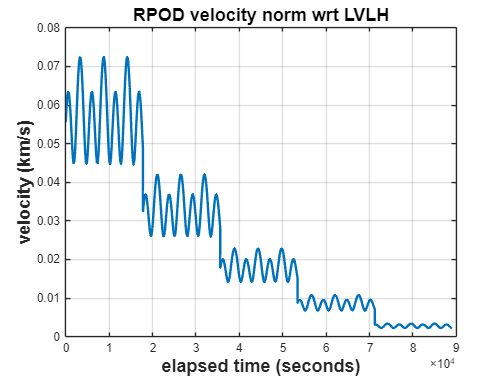


delta_v_t_norm = zeros(length(time_vector),1);

for i = 1:length(time_vector)
  delta_v_t_norm(i) = norm(delta_v_t_mat(i,:));
end

figure;
plot(time_vector, delta_v_t_norm,'LineWidth',2)
title('RPOD velocity norm wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
ylabel('velocity (km/s)','FontSize',15,'FontWeight','bold')
grid on


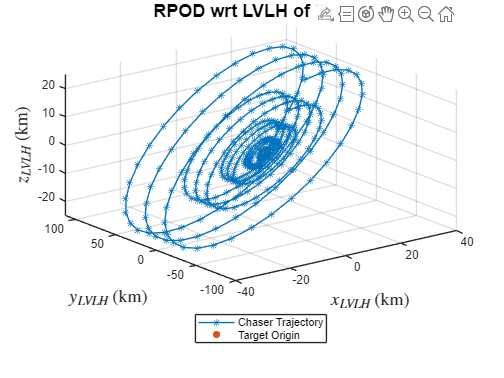


figure;
plot3(delta_r_t_mat(:,1),delta_r_t_mat(:,2),delta_r_t_mat(:,3),'*-')
hold on
scatter3(0,0,0,'filled','o')
hold off
grid on
title('RPOD wrt LVLH of Target','FontSize',15,'FontWeight','bold')
xlabel('$x_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
legend('Chaser Trajectory', 'Target Origin','Location','southoutside')


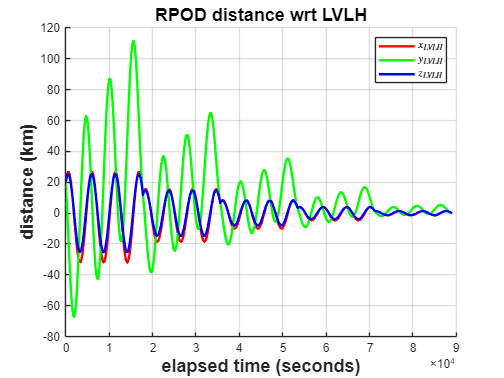



figure;
hold on
plot(time_vector, delta_r_t_mat(:,1),'r','LineWidth',2)
plot(time_vector, delta_r_t_mat(:,2),'g','LineWidth',2)
plot(time_vector, delta_r_t_mat(:,3),'b','LineWidth',2)
hold off
title('RPOD distance wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
ylabel('distance (km)','FontSize',15,'FontWeight','bold')
legend('$x_{LVLH}$','$y_{LVLH}$','$z_{LVLH}$', 'Interpreter', 'latex','Location','northeast')
grid on


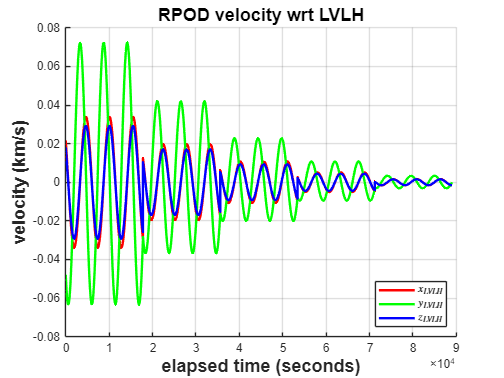




figure;
hold on
plot(time_vector, delta_v_t_mat(:,1),'r','LineWidth',2)
plot(time_vector, delta_v_t_mat(:,2),'g','LineWidth',2)
plot(time_vector, delta_v_t_mat(:,3),'b','LineWidth',2)
hold off
title('RPOD velocity wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
ylabel('velocity (km/s)','FontSize',15,'FontWeight','bold')
legend('$x_{LVLH}$','$y_{LVLH}$','$z_{LVLH}$', 'Interpreter', 'latex','Location','southeast')
grid on


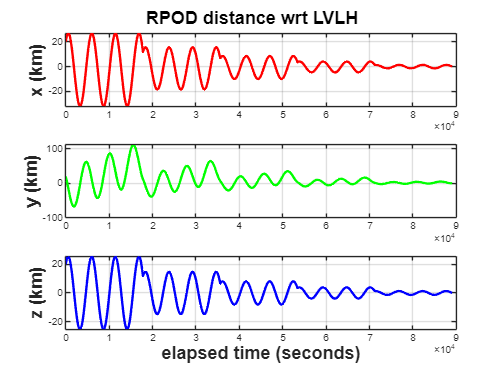



figure;
subplot(3,1,1)
plot(time_vector, delta_r_t_mat(:,1),'r','LineWidth',2)
ylabel('x (km)','FontSize',15,'FontWeight','bold')
grid on
subplot(3,1,2)
plot(time_vector, delta_r_t_mat(:,2),'g','LineWidth',2)
ylabel('y (km)','FontSize',15,'FontWeight','bold')
grid on
subplot(3,1,3)
plot(time_vector, delta_r_t_mat(:,3),'b','LineWidth',2)
ylabel('z (km)','FontSize',15,'FontWeight','bold')
sgtitle('RPOD distance wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
grid on


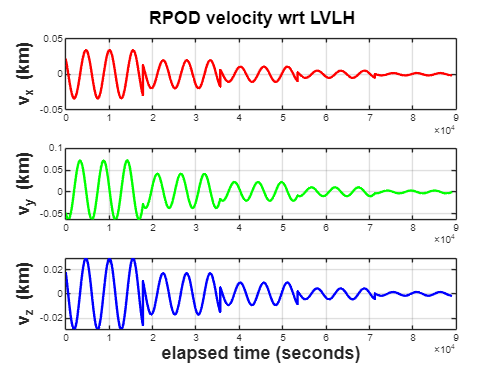


figure;
subplot(3,1,1)
plot(time_vector, delta_v_t_mat(:,1),'r','LineWidth',2)
ylabel('v_x (km)','FontSize',15,'FontWeight','bold')
grid on
subplot(3,1,2)
plot(time_vector, delta_v_t_mat(:,2),'g','LineWidth',2)
ylabel('v_y (km)','FontSize',15,'FontWeight','bold')
grid on
subplot(3,1,3)
plot(time_vector, delta_v_t_mat(:,3),'b','LineWidth',2)
ylabel('v_z (km)','FontSize',15,'FontWeight','bold')
sgtitle('RPOD velocity wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
grid on


## Appendix 1: Clohessy-Wilshire Matrix Generator 

function [Phi_rr, Phi_rv, Phi_vr, Phi_vv] = cw_matrix_generator(n,t)

nt = n*t;

Phi_rr = [4 - 3*cos(nt),   0, 0;
          6*(sin(nt) - nt),1,0;
          0,0, cos(nt)];

Phi_rv = [sin(nt)/n, 2/n * (1 - cos(nt)), 0;
          2/n*(cos(nt)-1), 4/n*sin(nt)-3*t,0;
          0,0,1/n*sin(nt)];

Phi_vr = [3*n*sin(nt),0,0;
          6*n*(cos(nt)-1),0,0;
          0,0,-n*sin(nt)];
Phi_vv = [cos(nt), 2*sin(nt),0
         -2*sin(nt), 4*cos(nt)-3, 0;
          0,0,cos(nt)];
end

## Appendix 2: Bundle Functions (kepler2ijk, ijk2kepler)

function [r,v] = kepler2ijk_hs(a,e,inc,RAAN,AOP,theta)

mu = 398600.4415;

RAAN = RAAN/180*pi;
inc = inc/180*pi;
AOP = AOP/180*pi;
theta = theta/180*pi;


R_3_AOP = [cos(AOP), sin(AOP),0;
           -sin(AOP), cos(AOP),0;
                    0,       0,1];

R_1_inc = [1,       0,         0;
           0, cos(inc),  sin(inc);
           0,-sin(inc),  cos(inc)];

R_3_RAAN = [cos(RAAN), sin(RAAN),0;
           -sin(RAAN), cos(RAAN),0;
                    0,       0,1];


Q_rotation = R_3_AOP * R_1_inc * R_3_RAAN;

p = Q_rotation(1,:);
q = Q_rotation(2,:);
w = Q_rotation(3,:);

p_value = a*(1-e^2);
r = p_value* (cos(theta)*p + sin(theta) *q)/(1+e*cos(theta));
r = r';
v = sqrt(mu/p_value)*(-sin(theta)*p+(e+cos(theta))*q)';
end


function [a, e, inc, RAAN, AOP, theta] = ijk2kepler_hs(r,v)

mu = 398600.4415;

h = cross(r,v);                                   % Angular Velocity Vector
z = [0,0,1]';
n = (cross(z,h))/(norm(cross(z,h)));              % Normal Vector
e_vector = ((cross(v,h))/mu) - r/(norm(r));       % Eccentricity vector


a = (-mu)/((norm(v))^2 - 2*mu/norm(r));           % 1. Semi-major axis
e = norm(e_vector);                               % 2. Eccentricity
inc = acos(dot(z,h)/norm(h)) / pi *180;           % 3. Inclination

RAAN = atan2(n(2),n(1));                          % 4. RAAN
RAAN = RAAN / pi * 180;

AOP = acos((dot(n,e_vector))/norm(e_vector));                   % 5. Argument of periapse
if(e_vector(3)<0)
    AOP = 2*pi - AOP;
end
AOP = AOP/pi*180;

theta = acos((dot(r,e_vector))/(norm(r)*norm(e_vector)));       % 6. True anomaly
if(dot(r,v) < 0)
    theta = 2*pi-theta;
end
theta = theta / pi * 180;

end